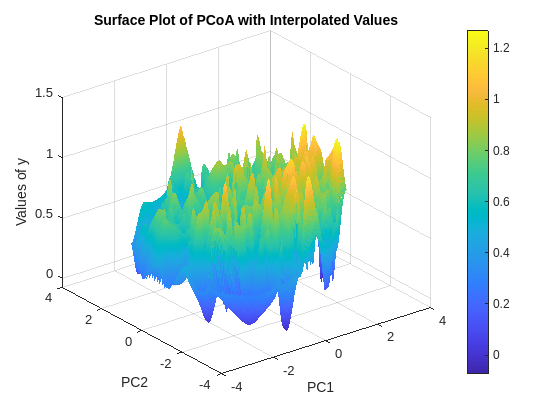

data = load('surface.mat');

% Access the variables
Y = data.Y;
y = data.y;

%%

% Extract columns from Y for x and y coordinates
x = Y(:, 1);  % First principal coordinate
y_coord = Y(:, 2);  % Second principal coordinate

% Create a grid for the surface plot
[xq, yq] = meshgrid(linspace(min(x), max(x), 1000), linspace(min(y_coord), max(y_coord), 1000));

% Interpolate the values of y on the grid
zq = griddata(x, y_coord, y, xq, yq, 'cubic');  % 'linear' or 'cubic' as interpolation method

% Create the surface plot
figure;
surf(xq, yq, zq, 'EdgeColor', 'none');  % 'EdgeColor' set to 'none' for a smoother appearance
colorbar;  % Show color scale
title('Surface Plot of PCoA with Interpolated Values');
xlabel('PC1');
ylabel('PC2');
zlabel('Values of y');